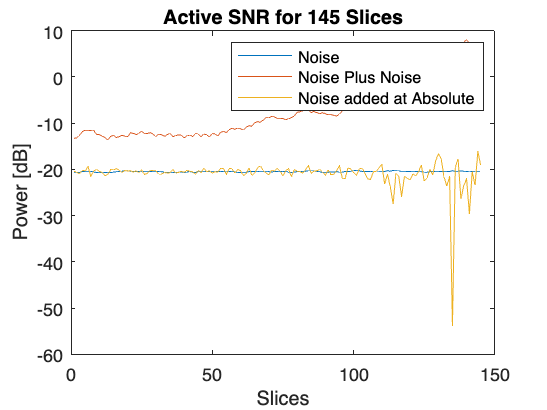

figure
plot(1:length(noise), noise,...
    1:length(noise_plus_noise), noise_plus_noise,...
    1:length(noise_plus_noise_abs_input), noise_plus_noise_abs_input)
legend('Noise', 'Noise Plus Noise', 'Noise added at Absolute')
title(figure_title);
ylabel('Power [dB]');
xlabel('Slices') ;


%%% 

SNR_minus20 = SNR - 20;
SNR_minus5 = SNR - 5;
SNR_minus10 = SNR - 10;
SNR_minus15 = SNR - 15;


% figure
% SNR_delta = SNR - SNR_plus_noise;
% figure_title = (inputstructure.name + ' SNR for '...
%     + length(inputdata) + ' Slices: -5, -10, -15 & -20 [dB]');
% fig = figure;
% plot(1:length(SNR), SNR, ...
%     1:length(SNR), SNR_minus20, ...
%     1:length(SNR), SNR_minus5, ...
%     1:length(SNR), SNR_minus10, ...
%     1:length(SNR), SNR_minus15)
%     %1:length(SNR_plus_noise), SNR_plus_noise, ...
%     %1:length(SNR_delta), SNR_delta, ...
% title(figure_title);
% ylabel('SNR [dB]');
% xlabel('Slice No') ;
% legend("SNR", 'SNR minus 20 (manually)', 'SNR minus 5 (manually)', ...
%     'SNR minus 10 (manually)', 'SNR minus 15 (manually)' )
% % legend("SNR", 'SNR + Noise', 'SNR Delta', 'SNR minus 20 (manually)')
% grid on
% %ylim([-max_doppler max_doppler]); % Doppler Limit
% xlim([-inf length(SNR)]);   % Range Limit
% 
% mean(SNR);
% mean(SNR_minus5);
% mean(SNR_minus10);
% mean(SNR_minus15);
% mean(SNR_minus20);


% mean(slices_range_doppler{1,1}, 'all')
mean_SNR = mean(SNR)

mean_SNR = 62.2783

mean_SNR_plus_noise = mean(SNR_plus_noise)

mean_SNR_plus_noise = 48.4627

mean_SNR_delta = mean_SNR - mean_SNR_plus_noise

mean_SNR_delta = 13.8157

mean(signal)

ans = 41.7676

mean(signal_plus_noise)

ans = 41.7683

mean_noise = mean(noise)

mean_noise = -20.5108

mean_noise_plus_noise = mean(noise_plus_noise)

mean_noise_plus_noise = -6.6943

mean_noise_delta = mean_noise - mean_noise_plus_noise

mean_noise_delta = -13.8165

noise_plus_noise_db = 20*log10(noise_plus_noise_abs);
mean_noise_plus_noise_abs_converted = mean(noise_plus_noise_db)

mean_noise_plus_noise_abs_converted = -6.6943


% applying awgn at abs
slices_range_doppler_abs_plus_noise = createArrays(length(slices_range_doppler_abs),...
    size(slices_range_doppler_abs{1,1})); % absolute when populated
for i=1:length(slices_range_doppler_abs)
    slices_range_doppler_abs_plus_noise{1,i} = awgn(slices_range_doppler_abs{1,i}, user_defined_noise,...
        'measured'); % absolute + awgn
end
%%%


signal_plus_noise_abs_input=zeros(1,length(inputdata)); % [dB] once func populates
noise_plus_noise_abs_input=zeros(1,length(inputdata)); % [dB] once func populates
noise_plus_noise_abs_abs_input=zeros(1,length(inputdata)); % absolute mean noise (not dB) once func populates
SNR_plus_noise_abs_input=zeros(1,length(inputdata)); % [dB] once func populates
slices_range_doppler_plus_noise_abs_input = createArrays(length(inputdata), size(inputdata{1,1})); % [dB]
slices_range_doppler_plus_noise_abs_abs_input = createArrays(length(inputdata), size(inputdata{1,1})); % Absolute

for i=1:length(inputdata)
    [signal_plus_noise_abs_input(i),...
        noise_plus_noise_abs_input(i),...
        SNR_plus_noise_abs_input(i),...
        slices_range_doppler_plus_noise_abs_input{i},...
        signal_idx_plus_noise_abs_input(i),...
        noise_plus_noise_abs_abs_input(i),...
        slices_range_doppler_plus_noise_abs_abs_input{i}]=slice_SNR_abs_input(slices_range_doppler_abs_plus_noise{1,i}, roi_indices_rows, roi_indices_cols);
end  

mean(slices_range_doppler_abs{1,1}, 'all')

ans = 0.1409

mean(inputdata_plus_noise_abs{1,1}, 'all')

ans = 0.2534